## Datastores

Create image datastore

file_dataset_train = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\train'

file_dataset_train = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\train'

imdsTr = imageDatastore(file_dataset_train, 'IncludeSubfolders',true, 'LabelSource', 'foldernames')

imdsTr =   ImageDatastore with properties:

                       Files: {
                              ' ...\Alzheimer Dataset\train\Mild Impairment\MildImpairment (1).jpg';
                              ' ...\Alzheimer Dataset\train\Mild Impairment\MildImpairment (10).jpg';
                              ' ...\Alzheimer Dataset\train\Mild Impairment\MildImpairment (100).jpg'
                               ... and 10237 more
                              }
                     Folders: {
                              ' ...\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\train'
                              }
                      Labels: [Mild Impairment; Mild Impairment; Mild Impairment ... and 10237 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputForma


file_dataset_test = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\test'

file_dataset_test = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\test'

imdsTest = imageDatastore(file_dataset_test, 'IncludeSubfolders',true, 'LabelSource', 'foldernames')

imdsTest =   ImageDatastore with properties:

                       Files: {
                              ' ...\Alzheimer Dataset\test\Mild Impairment\1 (10).jpg';
                              ' ...\Alzheimer Dataset\test\Mild Impairment\1 (11).jpg';
                              ' ...\Alzheimer Dataset\test\Mild Impairment\1 (14).jpg'
                               ... and 1276 more
                              }
                     Folders: {
                              ' ...\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\test'
                              }
                      Labels: [Mild Impairment; Mild Impairment; Mild Impairment ... and 1276 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     Rea

## Split dataset

[imdsTrain, imdsValidate, ~] = splitEachLabel(imdsTr, 0.33,0.1, "randomized");

## Create pretrained network

Define class

classNames = categories(imdsTrain.Labels)

classNames = 4×1 cell array
    {'Mild Impairment'     }
    {'Moderate Impairment' }
    {'No Impairment'       }
    {'Very Mild Impairment'}


numClasses = numel(classNames)

numClasses = 4

Create net using resnet-101 network

net = imagePretrainedNetwork('resnet101', NumClasses=numClasses)

net =   dlnetwork with properties:

         Layers: [346×1 nnet.cnn.layer.Layer]
    Connections: [378×2 table]
     Learnables: [418×3 table]
          State: [208×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


## Convert the image into resnet-101 image input type

Input_Layer_Size = net.Layers(1).InputSize(1:2);

augimdsTrain = augmentedImageDatastore(Input_Layer_Size, imdsTrain, 'ColorPreprocessing', 'gray2rgb');
augimdsValidate = augmentedImageDatastore(Input_Layer_Size, imdsValidate, 'ColorPreprocessing', 'gray2rgb');
augimdsTest = augmentedImageDatastore(Input_Layer_Size, imdsTest, 'ColorPreprocessing', 'gray2rgb');

## Train the network

Set up options

options = trainingOptions("adam", ...
    'InitialLearnRate', 0.0001, ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidate, ...
    'ValidationFrequency', 15, ...
    'ValidationPatience', 8, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'auto', ...
    'Metrics', 'accuracy');

Train the network

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:01:02       0.0001                             2.297                                    24.609
            1        1       00:01:02       0.0001          1.4592                                 31.25                      
           15        1       00:02:46       0.0001         0.48123            1.1571                  75                49.707
           30        1       00:04:02       0.0001          0.6091             0.845              65.625                61.133
           45        1       00:05:48       0.0001          0.6053           0.49518              65.625                78.516
           50        1       00:06:08       0.0001         0.56713                                71.875       

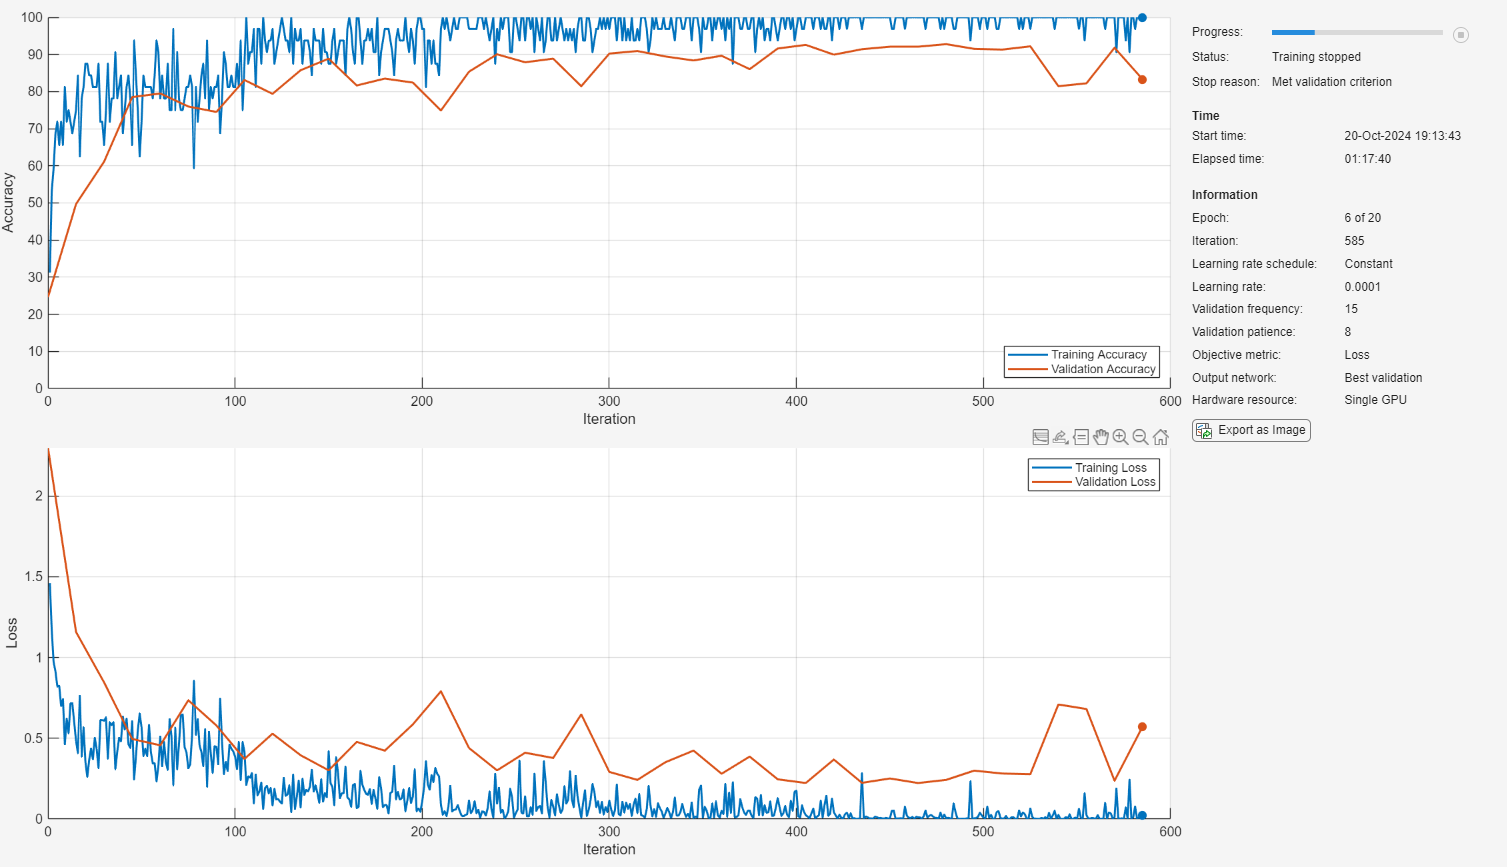

net = trainnet(augimdsTrain, net, "crossentropy", options);

## Check accuracy

accuracy = testnet(net,augimdsTest,"accuracy")

accuracy = 84.6755